# Digital Signal Processing -- Homework 5

#### Moving Average and Windowed SINC Filters

# **Problem 1 - Moving Average Filters**

**In this problem, you will create an impulse response for a moving average filter with a kernel of length 31. You will then plot the frequency response of the filter using the freqz function. See the background and example below first: **

Recall that the impulse response for a moving average filter is a kernel  with all the same values where the value is one over the length of the  filter.

For example:

 hMAV = [1/N, 1/N, 1/N, 1/N,...... 1/N];  where N is the  length of the filter.

 Hint:  One easy way to create a vector of all the same values in MATLAB  is to use the "ones(N,M)" function. This creates a matrix of size N by

 M of all ones. You can use "ones(1,N)" to create a row vector of all ones. Then you can scale the vector by the magnitude of the value that

 you want for all the elements. That is, if I want a vector of length 20 where all the values are 3, I would use

 x = ones(1,20) * 3;

Here is an example of creating a length 11 moving average filter in MATLAB

## 11-Point MAV Filter Example

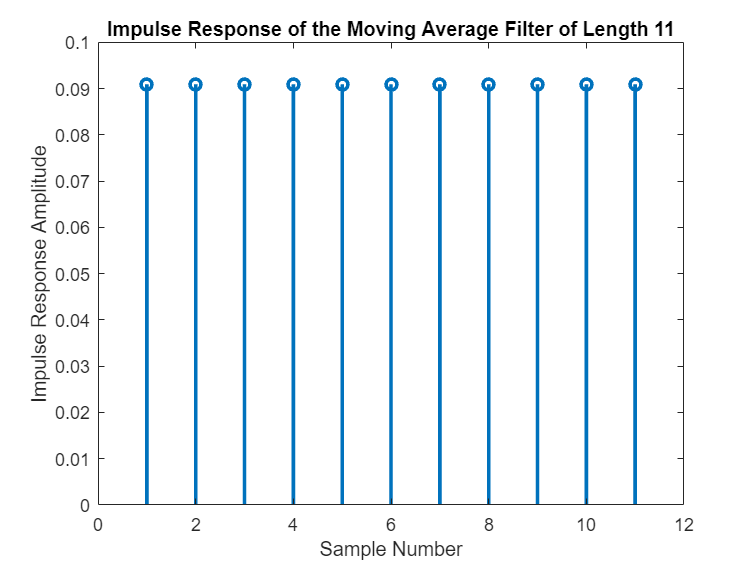

% Example

filterLength = 11;
hMAV11 = ones(1,filterLength) * (1/filterLength);

%  Plot the impulse response. Use the STEM function to plot the individual
%  values of the response

figure
stem( hMAV11, 'LineWidth',2 )
title('Impulse Response of the Moving Average Filter of Length 11');
xlabel('Sample Number');
ylabel('Impulse Response Amplitude')

## Plot the Frequency Response of a Digital Filter

To plot the frequency response of the filter, we use the freqz function. The freqz function is in the form of:

[h,w] = freqz(b, a, numFreqSamples )

where b is the numerator and a is  the denominator of the z-transform of the filter. In the case of an  FIR filter, the denominator a is just 1 and the numerator is the impulse response of the filter, hMAV.  


$$H(z) = \frac{h[0] + h[1]z^{-1}+h[2]z^{-2}+...+h[N-1]z^{n-1}}{1}
$$


The number of samples is the number of samples in the frequency domain and the output value h is a vector of the complex

value of the frequency response. The vector w is a vector of the frequency points corresponding to the points in the frequency response. The

frequency values represent the points around the circle in the z-domain from angle 0 to pi.

See <help freqz> in MATLAB for more (and better) information

## **11-Point MAV Filter Example**

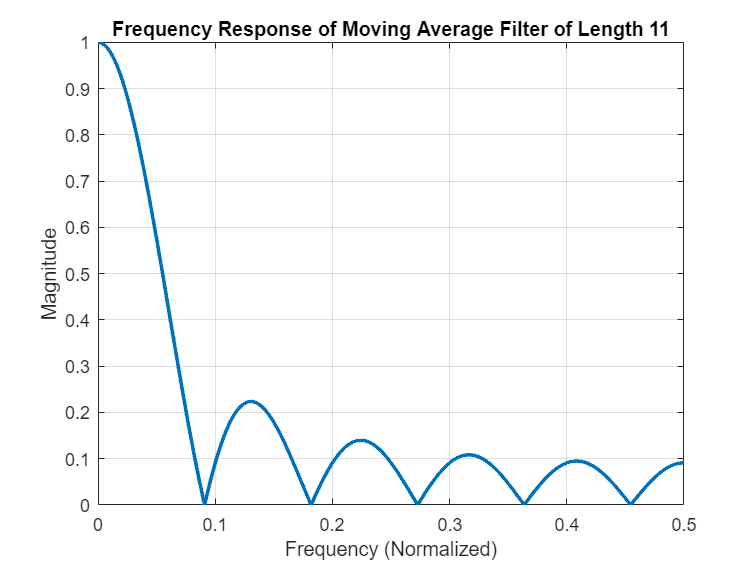

%  Compute the frequency response of the filter

nSamples = 2048;
[h,w] = freqz(hMAV11, 1, nSamples);

figure
plot(w/(2*pi), abs(h),'LineWidth',2 );
grid on
title('Frequency Response of Moving Average Filter of Length 11')
xlabel('Frequency (Normalized)');
ylabel('Magnitude')

## Your turn - Create a length 31 Moving Average Filter

**Now create your own impulse response of the moving average filter for a length of 31. Make sure to create a new variable name for the impulse response to keep it separate from the length 11 MAV impulse response. You'll use both again. **

**Plot the impulse response and the frequency response of your filter. Use appropriate titles and axes labels.**

%  Your solution goes here




%  Compute the frequency response.  Be sure to create a new variable for
%  the frequency respone and the frequency vector as you'll use these
%  again.






## Create a length 101 Moving Average Filter

**Now create another moving average filter with impulse response of length 101. As before, make sure to give it a new name. Plot the impulse response and the frequency response of your 101-point filter. Use appropriate titles and axes labels**

%   Moving Average filter of length 101.  Plot both frequency responses on
%   the same graph

%  Your solution goes here



%  Compute and plot the frequency response







# **Problem 2 - Apply the MAV filters to an Input Signal**

The moving average filter is an FIR filter. In this assignment, you will implement the filter using convolution. MATLAB has a function to perform convolution. It is "w = conv( u, v )". Use the MATLAB help function to better learn how to use this convolution function.

The input arguments u and v are  the input sequences to the function. Since convolution is commutative you can put them in either order.

The output is the variable w. The variable w includes the end effects, so you will want to remove the end effects of the result.

**Load the input signal file "HW_05_Problem_2_Signal.mat". Convolve the input sequence from the file (your filter input) with the impulse response of each of the three impulse responses from problem 1 (11, 31 and 101-point MAV filters) to obtain the filter output. Plot the input signal first and then the individual filter outputs. Finally, plot all three moving average filter outputs on the same x-axis, using a legend to distiguish the different filter outputs. Comment on the difference between the three filters below. **

- Load and plot the input sognal

% Load the file "HW_05_Problem_2_Signal.mat".  This will load two variables into the workspace.
% One "sample" is the sample number.
% The other is "signal" and is the signal of interest.
% 
%  Convolve the input signal from the file "HW_05_Problem_2_Signal.mat"
%  with the moving average filters of length 11, 31 and 101. The variable loaded into the workspace
%  is called "signal".


%  load the file "HW_05_Problem_2_Signal.mat" into the workspace



2. Determine and plot the output using the 11-Point MAV filter. Don't forget to remove the end effects.


%  Convolve the input signal with the length 11 MAV filter impulse response
%  filter.  Plot the output of the convolution.
%
%  Remove the end effects.  M-1 = 10 samples on the beginning and at the end

%  Place your solution here





3. Determine and plot the output using the 31-Point MAV filter. Don't forget to remove the end effects.


%  Convolve the input signal with the length 31 MAV filter impulse response
%  filter.  Plot the output of the convolution.
%
%  Remove the end effects.  M-1 = 30 samples on the beginning and at the end

%  Place your solution here



4. Determine and plot the output using the 101-Point MAV filter. Don't forget to remove the end effects.

%  Convolve the input signal with the length 101 MAV filter impulse response
%  filter.  Plot the output of the convolution.
%
%  Remove the end effects.  M-1 = 100 samples on the beginning and at the end

%  Place your solution here


5. Plot all three filter outputs for comparison

%  Plot all three convolution outputs with end effect removed on the same
%  graph below


## Questions:

#### Which filter removed the noise the best without distorting the output.  

#### Did any of the filters distort the output? 

####  Why?

# **Problem 3 - Windowed SINC Low Pass Filter**

**A)  I've done this first part for you as an example.** Using the FIR_Designer tool, I created a  truncated SINC lowpass filter with no window ('Window' parameter set to 'none') with a cut off frequency of 70 BPM assuming a sampling rate of 600 BPM. I used a filter kernel length of 201 and plotted the impulse response and the frequency response of the filter:

## Plot the impulse response -- Example


freqCornerLPF = 70;
filterLength = 201;

hLPF = FIR_Designer( 'nOrder', filterLength, 'cutBPM', freqCornerLPF, 'Window','none', 'PrintHeader',false,'PlotResponses',false);

h = [-0.002753, -0.000992, 0.001319, 0.002993, 0.003149, 0.001673, -0.000703, -0.002765, -0.003436, -0.002337, -0.000000, 0.002390, 0.003592, 0.002956,...
0.000768, -0.001870, -0.003599, -0.003498, -0.001577, 0.001213, 0.003441, 0.003935, 0.002395, -0.000431, -0.003108, -0.004238, -0.003192, -0.000455,...
0.002595, 0.004379, 0.003932, 0.001423, -0.001901, -0.004334, -0.004580, -0.002445, 0.001033, 0.004081, 0.005098, 0.003486, -0.000000, -0.003605,...
-0.005450, -0.004511, -0.001180, 0.002889, 0.005598, 0.005478, 0.002486, -0.001926, -0.005505, -0.006345, -0.003892, 0.000707, 0.005135, 0.007063,...
0.005368, 0.000773, -0.004448, -0.007583, -0.006881, -0.002518, 0.003402, 0.007847, 0.008397, 0.004540, -0.001944, -0.007792, -0.009878, -0.006860,...
0.000000, 0.007334, 0.011289, 0.009523, 0.002542, -0.006357, -0.012595, -0.012624, -0.005876, 0.004677, 0.013763, 0.016363, 0.010379, -0.001954,...
-0.014762, -0.021189, -0.016871, -0.002556, 0.015568, 0.028263, 0.027525, 0.010913, -0.016159, 

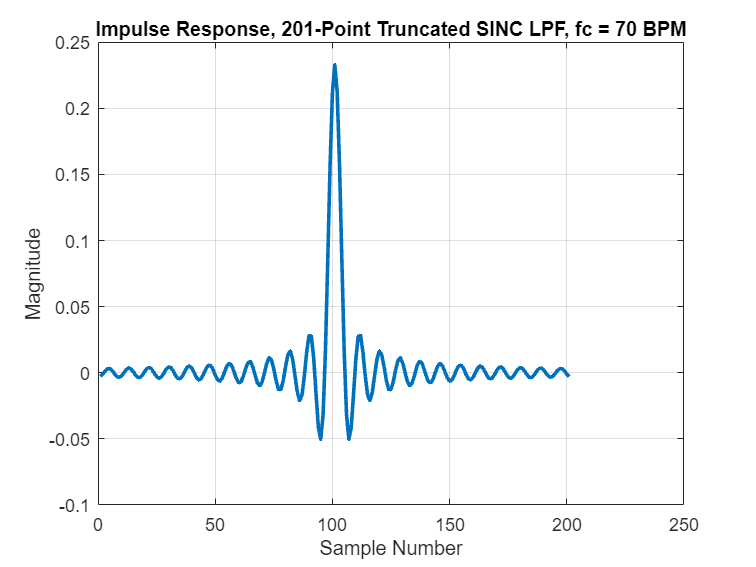


%  Plot the impulse response.

figure
plot(hLPF,'LineWidth',2)
grid on
title('Impulse Response, 201-Point Truncated SINC LPF, fc = 70 BPM')
xlabel('Sample Number')
ylabel('Magnitude')

## Plot the frequency response -- Example (continued)

Here, you'll see the plot of the magnitude of the frequency response (in dB) versus the frequency in breaths per minute. 

20*log10(abs( fResponseTruncatedSINC)) is used to find the gain in dB. The frequency response output is complex, so the magnitude is found using abs(). Then, the magnitude plot in decibels uses 20*log10( x ) where x is the magnitude of the frequency response.

The freqz function creates a vector of frequencies from 0 to pi (the Nyquist frequency). That vecore is converted to a vector of frequencies from 0 to 300 BPM. Where 300 BPM is the Nyquist frequency when sampling at 600 BPM. This is accomplished by dividing the frequency vector by $2\pi$ then multiplying by 600 BPM, the sample rate.

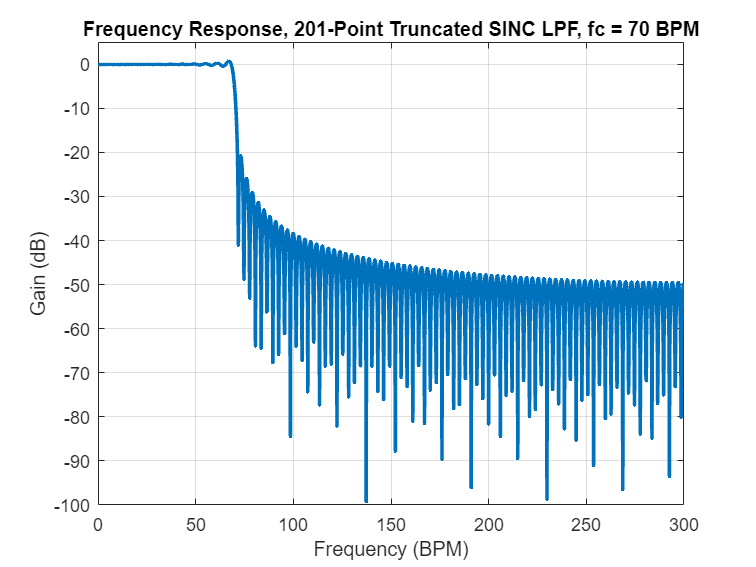

%  Plot the frequency response using the freqz function.

nSamples = 2048;  %  Use 2048 samples in the frequency response
[fResponseTruncatedSINC, wTruncatedSINC ] = freqz( hLPF, 1,  nSamples );


figure
plot(wTruncatedSINC/(2*pi)*600, 20*log10(abs(fResponseTruncatedSINC)),'LineWidth',2);
grid on
title('Frequency Response, 201-Point Truncated SINC LPF, fc = 70 BPM')
xlabel('Frequency (BPM)')
ylabel('Gain (dB)')
xlim([0,300])
ylim([-100,5])

## Questions

#### What does the pass-band look like?  

#### Is it flat? (Zoom in on the pass band to take a closer look) 

#### How much attenuation is achieved in the stop band of the filter?

**B)  Now, it's your turn. Create the same 201-point filter with fc=70 BPM, using a Hamming window and compare the frequency responses. Modify the parameters of the FIR_Designer command appropriately.**

## Create a Windowed SINC filter using a Hamming Window

Use the FIR_Designer function and use a Hamming window by changing the 'Window' parameter to the value 'Hamming'. Plot the impulse response and the frequency response as in the example. Create a separate variable for the Hamming window impulse response results as well as the frequency response results.


%  Create a 201-point windowed SINC low pass filter using a Hamming window

%  Put your solution here





## Questions

**What does the pass-band look like?  **

**Is it flat? (Zoom in on the pass band to take a closer look)**

**How does it compare to the truncated SINC filter?  **

**How much attenuation is achieved in the stop band of the filter?  **

**How does it compare to the truncated SINC filter?**

# **Problem 4 - Windowed SINC High Pass Filter**

**A) Using the FIR_Designer tool,  create a ****truncated**** SINC ****highpass**** filter ('Window' value of 'none') with a cut off frequency of 40 BPM assuming a sampling rate of 600 BPM. Use a filter length of 201. Plot the impulse response and then the frequency response of the filter in decibels.**

**B) Create the ****same filter using a Hamming window**** and compare the frequency responses below.**

Note:  You can supress the output of the C-header code by the FIR_Designer function by adding a parameter in Name/Value pair format 'PrintHeader','false'. You can also suppress the plotting of graphs using 'PlotResponses', false.

## Truncated SINC High Pass Filter


%  Place your solution here



%  Plot the impulse response




%  Plot the frequency response of the truncated SINC HPF 



## Questions

#### What does the pass-band look like?  

#### Is it flat? (Zoom in on the pass band to take a closer look)

#### How much attenuation is achieved in the stop band of the filter? 

## Hamming Windowed SINC High Pass Filter


%  Plot the results for the Hamming Windowed SINC High Pass Filter

%  Place your soluton here


%  Plot the impulse response



%  Plot the frequency response    

      

## Questions

#### What does the pass-band look like?  

#### Is it flat? (Zoom in on the pass band to take a closer look)

#### How does it compare to the truncated SINC filter?  

#### How much attenuation is achieved in the stop-band of the filter?  

#### How does it compare to the truncated SINC filter?

# **Problem 5 - Creating a Bandpass Filter **

**Combine the 201-point Hamming Windowed SINC LPF and the 201-point Hamming Windowed SINC HPF impulse responses in a way that they will create a bandpass filter. Refer to Chapter 14 of Smith and our lectures from weeks 7 and 8.  **

**Plot the impulse response and then the frequency response of this filter in decibels.**

By placing the lowpass and the highpass filters in series what do you know about the resulting impulse response of the cascaded system? How would you calculate the resulting impulse response?

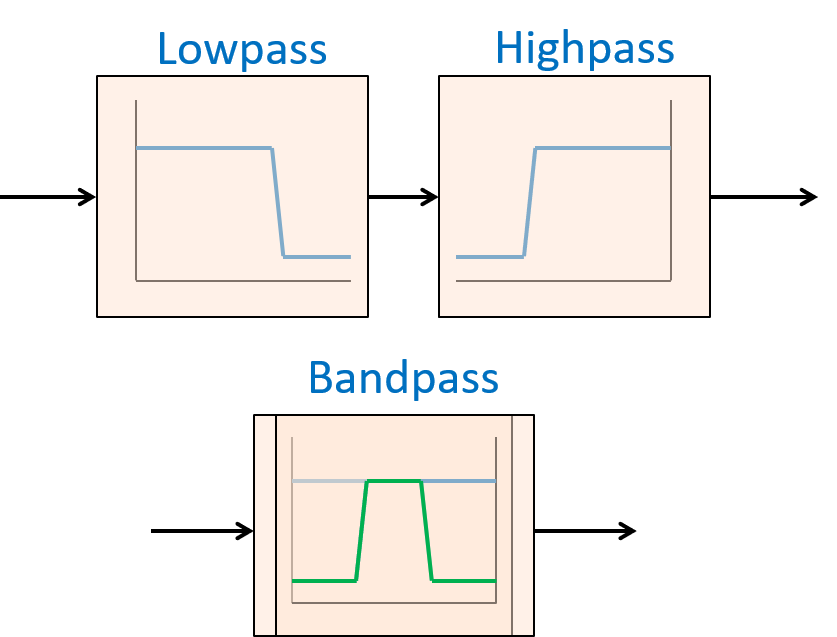

## Bandpass Filter Creation

%  Place your solution to create a bandpass filter from the lowpass and
%  high pass filter impulse responses.
%
%  Plot the impulse response and the frequency response of the bandpass
%  filter

%  Place your solution here

%  Plot the impulse response
    

    
%  Plot the frequency response
    
  
